format long g
f=@(x) (1 - x - 4.*x.^3 + 2.*x.^5)

f = function_handle with value:
    @(x)(1-x-4.*x.^3+2.*x.^5)


xx = linspace(-2,4)

xx =                         -2         -1.93939393939394         -1.87878787878788         -1.81818181818182         -1.75757575757576          -1.6969696969697         -1.63636363636364         -1.57575757575758         -1.51515151515152         -1.45454545454545         -1.39393939393939         -1.33333333333333         -1.27272727272727         -1.21212121212121         -1.15151515151515         -1.09090909090909         -1.03030303030303         -0.96969696969697        -0.909090909090909        -0.848484848484848        -0.787878787878788        -0.727272727272727        -0.666666666666667        -0.606060606060606        -0.545454545454545        -0.484848484848485        -0.424242424242424        -0.363636363636364        -0.303030303030303        -0.242424242424242        -0.181818181818182        -0.121212121212121       -0.0606060606060606                         0        0.0606060606060606         0.121212121212121         0.181818181818182         0.242424242424242       

yy = f(xx)

yy =                        -29          -22.755617836775         -17.4125350165769         -12.8787092287536         -9.06818165847983         -5.90088074495636         -3.30242593960919          -1.2039314642886         0.458189930531681          1.74242320755537          2.70234728446447          3.38683127572016          3.84023073436365          4.10258389381704          4.20980790968421          4.19389510155168          4.08310919478948          3.90218156235201          3.67250746657891          3.41234230099593           3.1369978321158          2.85903844123911          2.58847736625514          2.33297294344278          2.09802484927135           1.8871703422015          1.70218050448605          1.54325648397092          1.40922573589589          1.29773826469559          1.20546286580027          1.12828336743673          1.06149487242916                         1         0.938505127570841         0.871716632563266         0.794537134199726         0.702261735304409       

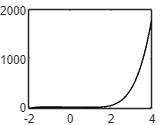

plot(xx,yy,'k-')

a = -2

a =     -2


b = 4

b =      4


p =[2 0 -4 0 -1 1]

p =      2     0    -4     0    -1     1


q = polyint(p)

q =          0.333333333333333                         0                        -1                         0                      -0.5                         1                         0


Itrue = diff(polyval(q,[a,b]))

Itrue =         1104


ns = 1

ns =      1


x = linspace(a,b,3*ns+1)

x =     -2     0     2     4


y = f(x)

y =          -29           1          31        1789



figure
color = ['g','y']

color = 'gy'

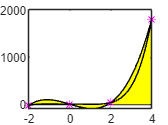

for i = 1:ns
    il = 3*(i-1)+1;
    ir = 3*i+1;
    newx = x(il:ir);
    newy = y(il:ir);
    p2 = polyfit(newx,newy,3);
    xx2 = linspace(x(il),x(ir));
    yy2 = polyval(p2,xx2);
    area(xx2,yy2,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
    plot(x(il:ir),y(il:ir),'m*')
    hold on
end
plot(xx,yy,'k-')